# **Modèle de Cox-Ross-Rubinstein**

## 1- Hypothèses  du modèle

On considère sur le marché financier un actif sans risque $S^0$ et une action S sur un horizon de temps [0,T]. Les agents interviennent sur le marché aux dates tk= kΔt, k = 0,...N où Δt >0  est le pas de temps. L'actif sans risque est un placement bancaire au taux sans risque r > 0 : une unité monétaire investie en S0 sur un intervalle de temps τ rapporte exp(r τ) unités monétaires. 

Pour une suite finie de N instants régulièrement répartis entre 0 et T, ou Δt > 0 est un réel fixé (supposé petit), la valeur (St)tϵ[0,T] de l’actif risqué est égale à un nombre positif donné S0 à l’instant t = 0, et elle évolue selon la règle suivante : si sa valeur à l’instant t ∈ [0,T]\{N*Δt} est St, alors sa valeur à l’instant t + Δt sera soit  $uS_t$  soit  $dS_t$ , ou u et d sont des constantes qu’on supposera telles que 0 <d< 1 < u.

Donc (St) évolue sur un arbre binaire qui, à tout instant tk = kΔt ∈ [0,T], présente k + 1 nœuds ou k + 1 valeurs possibles égales à : $S_{t_k}=S_{k\triangle t}$∈ {$S_0 u^j d^{k-j}$ , j = 0,...,k} , l’indice j représentant le nombre de fois ou l’actif a évolué à la hausse entre l’instant t = 0 et l’instant tk = kΔt (j est nombre de “up”), l’ordre des “up” et des “down” n’important pas. En pratique, on prend souvent pour u et d les valeurs u = exp(σ √Δt) et d = 1/u = exp(−σ √δt), ou σ  est la volatilité de l’actif S que l’on supposera constante. 

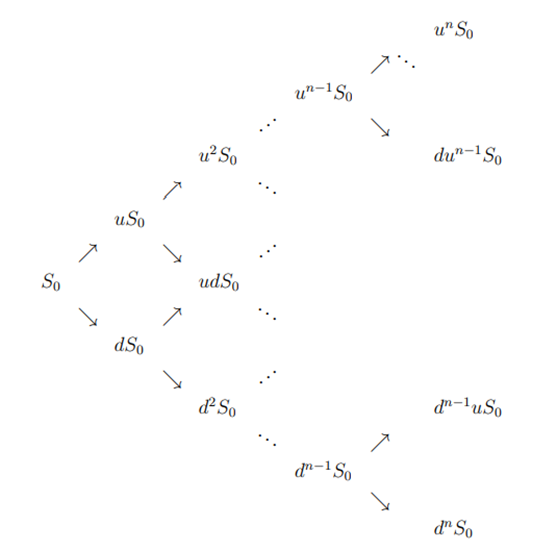

## 2- Modèle de Cox-Ross-Rubinstein

La formule fondamentale pour l’évaluation du prix d’une option européenne dans un modèle de Cox-Ross-Rubinstein.

1) Option européenne

- Pour un call


$$C = e^{-rT}\sum_{j=0}^{N}C_N^Jq^j(1-q)^{N-j}(S_0u^jd^{N-j}-K)^+$$


- Pour un Put


$$C = e^{-rT}\sum_{j=0}^{N}C_N^Jq^j(1-q)^{N-j}(K-S_0u^jd^{N-j})^+$$


2) Option Américaine

Pour une option américaine, l’approche itérative est appliquée avec une complication supplémentaire : il faut, à chaque nœud, vérifier si l’option doit être exercée. Pour cela, la valeur de l’option non exercée est comparée à sa valeur intrinsèque. La valeur de l’option est donnée par le maximum de ces deux valeurs. Formellement, la valeur de l’option au nœud k (lorsque le cours de l’action est Stk) est : 

                              
$$V_{t_k} = Max[(\theta(S_{t_k}-K))^+ , (qS_{t_{k+1}}^u+(1-q)S_{t_{k+1}}^d)e^{-r\triangle t}]$$


 Avec θ = 1 pour un call et θ = -1 pour un put. 

## Application: Call et Put européens

- So = 100 

- K = 100 

- r = 0.06 

- sigma = 0.1

%European options pricing
%CRR with 200 steps
Ce = CoxRossRubinstein(100, 100, 0.06, 0.1, 1/200, 200, 'CALL', false)

Ce = 7.4538

Pe = CoxRossRubinstein(100, 100, 0.06, 0.1, 1/200, 200, 'PUT', false)

Pe = 1.6303

## Application: Call et Put américains

- So = 100 

- K = 100 

- r = 0.06 

- sigma = 0.1

%American options pricing
%CRR with 200 steps 
Ca = CoxRossRubinstein(100, 100, 0.06, 0.1, 1/200, 200, 'CALL', true)

Ca = 7.4538

Pa = CoxRossRubinstein(100, 100, 0.06, 0.1, 1/200, 200, 'PUT', true)

Pa = 2.2333

## 3) Convergence du modèle CRR vers le modèle de Black-Scholes 

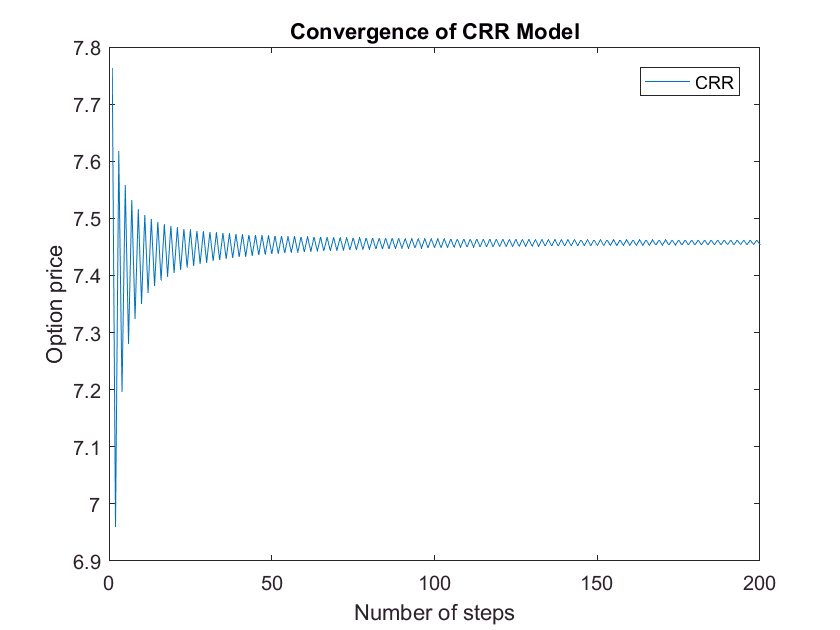

% Visualizing option price vs number of steps of CRR
%Initialize the vector containing the number of steps and the price
N = 1:200; 
ValueCall = zeros(size(N)); 
%For each number of step compute the call's price using CRR
for i = N
    ValueCall(i) = CoxRossRubinstein(100, 100, 0.06, 0.1, 1/i, i, 'CALL', false);
end
%Plot Option price VS Number of steps
plot(N, ValueCall);
legend('CRR');
title('Convergence of CRR Model');
xlabel('Number of steps');
ylabel('Option price');

On démontre que pour N assez grand le moèle de CRR converge vers le modèle de Black-Scholes. 

Formule de BS pour un call européen: 


$$C = S_0 N(d_1) - Ke^{-rT}N(d_2)$$


avec $d_1 = \frac{ln(S_0/K)+rT}{\sigma \sqrt{T}}+\frac{1}{2}\sigma\sqrt{T} \;\;\;\;\;  et \;\;\;\;\; d_2 = d_1-\sigma\sqrt{T}$

Formule de BS pour un put européen: 


$$P = -S_0N(-d_2) + Ke^{-rT}N(-d1)$$


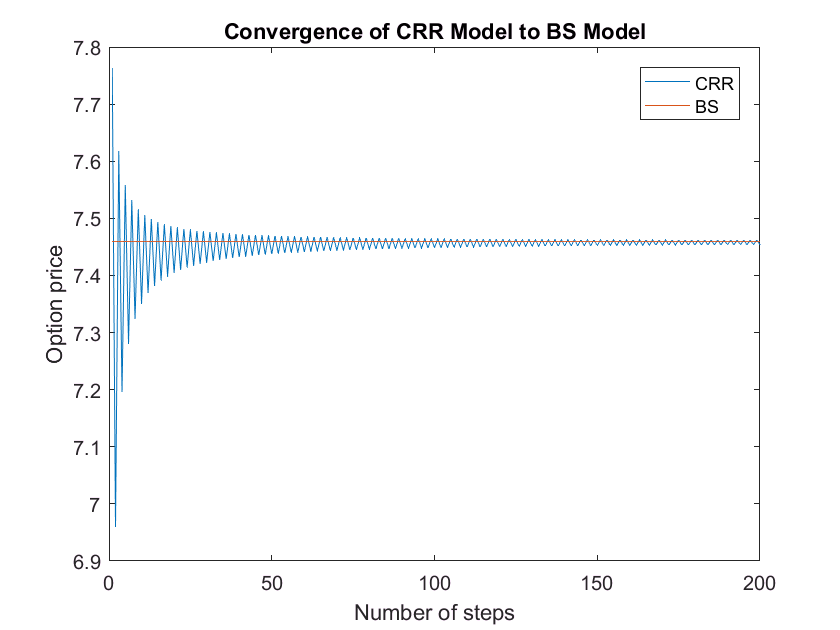

% Convergence of CRR to BS
% European call pricing
%Initialize the vector containing the number of steps
N = 1:200; 
ValueCall = zeros(size(N)); 

%For each number of step compute the call's price using CRR
for i = N
    ValueCall(i) = CoxRossRubinstein(100, 100, 0.06, 0.1, 1/i, i, 'CALL', false);
end

%Compute the call price using BS 
Cbs = CallBS(100, 100, 1, 0.06, 0.1)*ones(size(N));

%Plot CRR and BS
plot(N, ValueCall);
hold on
plot(N, Cbs); 
hold off
legend('CRR', 'BS');
title('Convergence of CRR Model to BS Model');
xlabel('Number of steps');
ylabel('Option price');